## **Creating the Learning Factory Environment**

## **Creating the Learning Factory Environment**

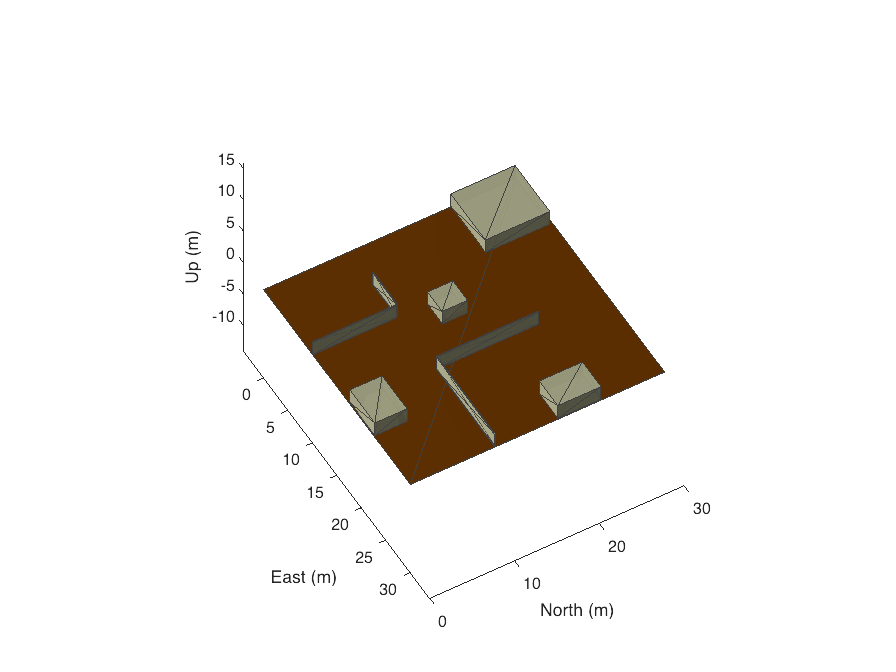

envc = EnvironmentConstants();
[obstacles, scenario, gridSize] = envc.createRobotScenerioEnvironment3();
show3D(scenario);
lightangle(-45,30);
view(60,50);

## Load the agent and create the simulink things

contents = load("experiments_comparison_points/experiment_3_points.mat", "points");
importantCoordinates = contents.points;

## Creating the variables for statistics

numTrials = 100;

numFailures = zeros(numTrials,3);
runTimes = zeros(numTrials,1);
numDeadlocks = zeros(numTrials,1);
numCollisions = zeros(numTrials,1);

distancesTravelled = zeros(numTrials,2);
safetyScores = zeros(numTrials,2);
smoothnessScores = zeros(numTrials,2);

## Create the tasks

for trial=1:numTrials
    %step 1
    rng(trial)
    selected_indices = randperm(length(importantCoordinates),6);
    locations = importantCoordinates(selected_indices,:);
    %format the input string

    stringInput = embedJSON([locations(1,:); locations(4,:)],[locations(2,:); locations(5,:)], [locations(3,:); locations(6,:)],[locations(1,:); locations(4,:)], [1; 2]);
    tic
    taskControlAgent = TaskControlAgent(gridSize, obstacles);
    reservedRoutes = taskControlAgent.executeControl(stringInput, taskControlAgent.DECENTRALISED);
    toc

    taskControlAgent.tasks.startCoordinates

    runTimes(trial) = toc;

    %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% ANALYSE THE ROUTES %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
    [maxElements, longestIdx] = max(cellfun(@numel, reservedRoutes));
    numRows = maxElements/2;
    [minElements, shortestIdx] = min(cellfun(@numel, reservedRoutes));
    
    waypoints = {};
    for rIndex=1:length(reservedRoutes)
        thisRoute = reservedRoutes{rIndex};
        currentLength = size(thisRoute,1);
        if currentLength < numRows
            %if the current route is shorter than the longest one then repeat
            %the end to the right length
            temp = zeros(numRows-currentLength,2);
            temp = temp+thisRoute(end,:);
            reservedRoutes{rIndex} = [thisRoute; temp];
        end
        %adjust the coordinates correctly
        temp = zeros(length(reservedRoutes{rIndex}), 2);
        for rIndex2=1:numRows
            currentCoords = reservedRoutes{rIndex}(rIndex2,:);
            temp(rIndex2,:) = [currentCoords(1)-0.5, currentCoords(2)-0.5]; 
        end
        waypoints{rIndex} = temp;
    end
    route1 = waypoints{1};
    route2 = waypoints{2};
    
    %Calculate the Distance Travelled
    travelDistance1 = distanceTravelled(route1);
    travelDistance2 = distanceTravelled(route2);

    %Calculate the Number of Collisions
    totalLength = size(reservedRoutes{longestIdx},1);
    collisions = 0;
    for lIndex=1:totalLength 
        amr1loc = route1(lIndex,:);
        amr2loc = route2(lIndex,:);
    
        locations = [amr1loc; amr2loc];
        collisions = collisions + checkCollisions(locations);
    end

    %Calculate the Number of Deadlocks
    routes = {route1, route2};
    deadlocks = checkDeadlocks(route1, route2);
    
    disp("check")
    numFailures(trial, :)
    deadlocks
    collisions
    disp("__________")

    failures = [0 0 0];
    numFailures(trial,:) = failures;
    numDeadlocks(trial) = deadlocks;
    numCollisions(trial) = collisions;
    
    distancesTravelled(trial,:) = [travelDistance1 travelDistance2];
    smoothnessScores(trial,:) = calculateSmoothnessScores({route1, route2});
    safetyScores(trial,:) = calculateSafetyScores({route1, route2});

     
        [obstacles, robotScenario, gridSize] = envc.createRobotScenerioEnvironment3();
        tasks = taskControlAgent.getTasks();
        robots = taskControlAgent.getMobileRobots();
        %temp = simulateExperiment(waypoints, importantCoordinates, tasks, robots, robotScenario)

    %if collisions > 0 || deadlocks > 0 
    %    [obstacles, scenario, gridSize] = envc.createRobotScenerioEnvironment1();
    %    travelDistances = simulateExperiment(waypoints, tasks, robots, scenario);
    %end
end

Elapsed time is 2.225201 seconds.


ans =      4     2


ans =     10    14


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.533661 seconds.


ans =      3    10


ans =      9    25


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.326956 seconds.


ans =     17     8


ans =      3    10


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.817634 seconds.


ans =      8    21


ans =      4     2


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.594851 seconds.


ans =      4     2


ans =     10    14


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.928788 seconds.


ans =     15     6


ans =      9    21


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.256563 seconds.


ans =     15     6


ans =      8    21


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.553553 seconds.


ans =     15     6


ans =     17     8


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.492718 seconds.


ans =      3    10


ans =      9    25


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.155334 seconds.


ans =      4     2


ans =     21    21


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.813215 seconds.


ans =     21    21


ans =     16     9


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.222685 seconds.


ans =     11    24


ans =     15     6


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.534720 seconds.


ans =      8    21


ans =     16     9


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.729114 seconds.


ans =     16     9


ans =     15     6


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.253936 seconds.


ans =      8    21


ans =     22    24


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.738576 seconds.


ans =      9    25


ans =     15     6


check


ans =      0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.871484 seconds.


ans =     15     6


ans =     21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.915654 seconds.


ans = 1×2
    11    24


ans = 1×2
    21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.345690 seconds.


ans = 1×2
     9    25


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.195429 seconds.


ans = 1×2
    21    21


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.082665 seconds.


ans = 1×2
     9    25


ans = 1×2
    21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.122766 seconds.


ans = 1×2
    17     8


ans = 1×2
    21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.531754 seconds.


ans = 1×2
    22    24


ans = 1×2
    21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.868909 seconds.


ans = 1×2
     9    21


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.322824 seconds.


ans = 1×2
    10    14


ans = 1×2
     3    10


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.948548 seconds.


ans = 1×2
    15     6


ans = 1×2
     3    10


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.666152 seconds.


ans = 1×2
     4     2


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.139000 seconds.


ans = 1×2
    22    24


ans = 1×2
     9    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.748902 seconds.


ans = 1×2
    21    21


ans = 1×2
     9    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.013060 seconds.


ans = 1×2
    15     6


ans = 1×2
    11    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.082259 seconds.


ans = 1×2
     4     2


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.082283 seconds.


ans = 1×2
     4     2


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.044214 seconds.


ans = 1×2
     9    25


ans = 1×2
    11    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.856070 seconds.


ans = 1×2
    21    21


ans = 1×2
    17     8


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.818123 seconds.


ans = 1×2
     3    10


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.969243 seconds.


ans = 1×2
    10    14


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.571289 seconds.


ans = 1×2
    21    21


ans = 1×2
     3    10


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.981217 seconds.


ans = 1×2
    15     6


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.145289 seconds.


ans = 1×2
    15     6


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.447792 seconds.


ans = 1×2
     9    25


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.502111 seconds.


ans = 1×2
     9    21


ans = 1×2
    21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.602779 seconds.


ans = 1×2
     4     2


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.499083 seconds.


ans = 1×2
     9    25


ans = 1×2
    10    14


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.260743 seconds.


ans = 1×2
     3    10


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.377008 seconds.


ans = 1×2
     3    10


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.651627 seconds.


ans = 1×2
    22    24


ans = 1×2
    21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.359066 seconds.


ans = 1×2
    16     9


ans = 1×2
    15     6


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.066634 seconds.


ans = 1×2
    16     9


ans = 1×2
    15     6


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.049484 seconds.


ans = 1×2
     3    10


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.147389 seconds.


ans = 1×2
    10    14


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.326698 seconds.


ans = 1×2
    10    14


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.243853 seconds.


ans = 1×2
    21    21


ans = 1×2
     8    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.536907 seconds.


ans = 1×2
     9    21


ans = 1×2
    10    14


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.510440 seconds.


ans = 1×2
    11    24


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.343749 seconds.


ans = 1×2
     9    25


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.279836 seconds.


ans = 1×2
     9    21


ans = 1×2
    15     6


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.561301 seconds.


ans = 1×2
     4     2


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.295088 seconds.


ans = 1×2
    22    24


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.705741 seconds.


ans = 1×2
     4     2


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.536218 seconds.


ans = 1×2
     4     2


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.854109 seconds.


ans = 1×2
     9    21


ans = 1×2
    17     8


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.612584 seconds.


ans = 1×2
     9    25


ans = 1×2
    10    14


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.037319 seconds.


ans = 1×2
    15     6


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.219867 seconds.


ans = 1×2
    15     6


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.282162 seconds.


ans = 1×2
    15     6


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.295725 seconds.


ans = 1×2
    11    24


ans = 1×2
    10    14


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.777425 seconds.


ans = 1×2
    21    21


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.631430 seconds.


ans = 1×2
     9    25


ans = 1×2
     8    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.388161 seconds.


ans = 1×2
    11    24


ans = 1×2
     9    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.438006 seconds.


ans = 1×2
     9    21


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.077877 seconds.


ans = 1×2
     9    21


ans = 1×2
     8    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.608359 seconds.


ans = 1×2
     4     2


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.579567 seconds.


ans = 1×2
    10    14


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.519063 seconds.


ans = 1×2
     9    25


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.007875 seconds.


ans = 1×2
     3    10


ans = 1×2
     9    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.192608 seconds.


ans = 1×2
     9    25


ans = 1×2
     3    10


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.629844 seconds.


ans = 1×2
     4     2


ans = 1×2
     9    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.109372 seconds.


ans = 1×2
    15     6


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.761932 seconds.


ans = 1×2
    16     9


ans = 1×2
     8    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.426580 seconds.


ans = 1×2
    15     6


ans = 1×2
    11    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.090577 seconds.


ans = 1×2
    21    21


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.393448 seconds.


ans = 1×2
    17     8


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.442668 seconds.


ans = 1×2
    15     6


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.045775 seconds.


ans = 1×2
    10    14


ans = 1×2
    15     6


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.799858 seconds.


ans = 1×2
     8    21


ans = 1×2
     4     2


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.180867 seconds.


ans = 1×2
    22    24


ans = 1×2
    11    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 1.800669 seconds.


ans = 1×2
    11    24


ans = 1×2
     3    10


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.246019 seconds.


ans = 1×2
     4     2


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.299831 seconds.


ans = 1×2
    21    21


ans = 1×2
    11    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.553458 seconds.


ans = 1×2
    22    24


ans = 1×2
     9    25


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.049758 seconds.


ans = 1×2
     9    25


ans = 1×2
    17     8


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.208478 seconds.


ans = 1×2
    22    24


ans = 1×2
    15     6


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.067302 seconds.


ans = 1×2
    21    21


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.211730 seconds.


ans = 1×2
     8    21


ans = 1×2
    11    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.955741 seconds.


ans = 1×2
    15     6


ans = 1×2
    16     9


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.891240 seconds.


ans = 1×2
    16     9


ans = 1×2
    22    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.881181 seconds.


ans = 1×2
     8    21


ans = 1×2
    17     8


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.515364 seconds.


ans = 1×2
    22    24


ans = 1×2
    21    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 2.599412 seconds.


ans = 1×2
     3    10


ans = 1×2
     8    21


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________


Elapsed time is 3.101283 seconds.


ans = 1×2
     8    21


ans = 1×2
    11    24


check


ans = 1×3
     0     0     0


deadlocks = 0

collisions = 0

__________



%Run Times
runTimes

runTimes = 100×1
    2.2344
    2.5410
    1.3338
    1.8260
    1.6028
    1.9359
    1.2739
    2.5750
    3.5013
    2.1633


numFailures

numFailures = 100×3
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0
     0     0     0


numDeadlocks

numDeadlocks = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


numCollisions

numCollisions = 100×1
     0
     0
     0
     0
     0
     0
     0
     0
     0
     0


distancesTravelled

distancesTravelled = 100×2
    86    26
    82    50
    10    44
    40    52
    52    26
    50    46
    28    14
    40    60
    76    78
    60    36


smoothnessScores

smoothnessScores = 100×2
   15.7080   10.9956
   17.2788   15.7080
    9.4248   10.9956
   10.9956   12.5664
   12.5664    7.8540
   12.5664    7.8540
   12.5664   10.9956
   18.8496   12.5664
   23.5619   15.7080
   14.1372   12.5664


safetyScores

safetyScores = 100×2
     3     3
     1     1
     0     0
     4     4
     0     0
     0     0
     0     0
     2     2
    14    14
     4     4


save('experiments_comparison_results/experiment_3_new_decentralised_ga.mat','runTimes','numFailures','numDeadlocks','numCollisions','distancesTravelled','smoothnessScores','safetyScores');